# Лабораторная работа №3

**Задания:**

- Ознакомиться с основами методов GlobalSearch и MultiStart, уяснить синтаксис и параметры создания глобальных объектов и проблемы, параметры команды run.

- Воспроизвести программу из примера 8 и провести пять запусков; сделать анализ результатов.

- Применить методы GlobalSearch и MultiStart для нахождения минимумов функции $f=-\exp \left(x_1 \sin \left(x_1 \right)-{x_2 }^2 \right)+0,4x_1$ при условиях $-4\le x_j \le 4,j=1,2\ldotp$Сравнить эффективность методов.

- Применить методы GlobalSearch и MultiStart для нахождения минимумов функции из примера 9 при дополнительном ограничении $4x_1 -5x_2 \le 5\ldotp$ Сопоставить решения при разном числе стартовых точек и разных значениях параметра StartPointsToRun.

## 1. Ознакомиться с основами методов GlobalSearch и MultiStart, уяснить синтаксис и параметры создания глобальных объектов и проблемы, параметры команды run.

   Основные отличия между двумя методами оптимизации в MATLAB: GlobalSearch и MultiStart. Эти методы часто используются для нахождения глобального минимума многомерных функций, особенно когда функция имеет множество локальных минимумов.

    **1.1 Генерация стартовых точек**

**- GlobalSearch:**

  - Использует алгоритм поискового рассеяния, который автоматически генерирует стартовые точки, при этом стараясь "разбросать" их по области поиска. 

  - Он применяет специальные стратегии для исключения из рассмотрения тех стартовых точек, которые, как предполагается, не приведут к улучшению лучшего найденного решения.

**- MultiStart:**

  - Принимает фиксированные стартовые точки, которые могут быть равномерно распределены по области поиска или предоставлены пользователем.

  - Работает с каждым из заданных стартовых значений, не исключая их, и пытается найти локальный минимум из каждой стартовой позиции.

**    1.2. Анализ стартовых точек**

**- GlobalSearch:**

  - Анализирует каждую стартовую точку на предмет ее стоимости и исключает те, которые, скорее всего, не приведут к улучшению текущего лучшего решения (локального минимума). Таким образом, он уменьшает количество запусков локальных оптимизаторов.

**- MultiStart:**

  - Запускает локальный оптимизатор из каждой стартовой точки, независимо от их "обещающих" характеристик. Это может привести к большему количеству вычислений, но обеспечит более обширное покрытие области поиска.

**    1.3. Выбор локального решателя**

**- GlobalSearch:**

  - По умолчанию использует алгоритм fmincon для решения оптимизационных задач, но можно настроить другие алгоритмы.

**- MultiStart:**

  - Позволяет выбирать из различных локальных решателей, таких как fminunc, lsqcurvefit, lsqnonlin, и других. Это предоставляет пользователю гибкость в зависимости от характера задачи.Заключение

**    1.4.** **Выбор между**   

    Выбор между GlobalSearch и MultiStart зависит от специфической задачи и требований. Если нужно управлять стартовыми точками и есть четкие данные об области поиска, MultiStart может быть лучше. Если же нужно более автоматизированное решение, которое самостоятельно определяет стартовые точки, тогда стоит рассмотреть GlobalSearch. 

## 2. Воспроизвести программу из примера 8 и провести пять запусков; сделать анализ результатов.

В примере 8 необходимо найти минимумы следующей функции:

при условиях

clc; 
clear; 
close all;

% анонимные функции
fun1 = @(x) 4*x(1)^2 - 2.1*x(1)^4 + x(1)^6/3 + ...
    x(1)*x(2) - 4*x(2)^2 + 4*x(2)^4;

fun2 = @(x,y) 4*x.^2 - 2.1*x.^4 + x.^6/3 + ...
    x.*y - 4*y.^2 + 4*y.^4;


[x, y] = meshgrid(-3:0.03:3);
Z = fun2(x,y);

% 3D функции
meshc(x,y,Z);
xlabel('x1'); ylabel('x2'); zlabel('f');
figure;

% контуры уровня
contour(x,y,Z,[-0.8 -0.2 0.07 1 3 7 15 28 45 65],'blue');
xlabel('x1'); ylabel('x2');

% нач точ для оптимизации
x0 = [0, 1];

% % MultiStart с выводом информации по итерациям
% ms = MultiStart('Display','iter');
% opts = optimset('Algorithm','interior-point');

% MultiStart без вывода информации по итерациям
ms = MultiStart('Display','off');
opts = optimset('Algorithm','interior-point');

problem = createOptimProblem('fmincon','x0',x0,...
    'objective',fun1,'lb',[-3,-3],'ub',[3,3],...
    'options',opts);

% MultiStart с 40 стартовыми точками
[x,fval,flag,outpt,manyminms] = run(ms,problem,40);

% график стартовых и конечных точек локальных поисков
possColors = 'kbgcrm';
hold on;

for i = 1:size(manyminms,2)
    % определение цвета для каждой линии
    cIdx = rem(i-1, length(possColors)) + 1;
    color = possColors(cIdx);
    
    % график стартовых точек
    u = manyminms(i).X0;
    x0ThisMin = reshape([u{:}], 2, length(u));
    plot(x0ThisMin(1, :), x0ThisMin(2, :), '.', ...
        'Color',color, 'MarkerSize',12);
    
    % график c центром с цветом i
    plot(manyminms(i).X(1), manyminms(i).X(2), '*', ...
        'Color', color, 'MarkerSize',10);
end 

hold off;

% лучш минимум
disp('Лучшая найденная точка (x):');

Лучшая найденная точка (x):


disp(x);

   -0.0898    0.7127



disp('Значение целевой функции в этой точке (fval):');

Значение целевой функции в этой точке (fval):


disp(fval);

   -1.0316



disp('Значение флага (flag):');

Значение флага (flag):


disp(flag);

     1



disp('Структура выходных данных (outpt):');

Структура выходных данных (outpt):


disp(outpt);

                funcCount: 1602
         localSolverTotal: 40
       localSolverSuccess: 40
    localSolverIncomplete: 0
    localSolverNoSolution: 0
                  message: 'MultiStart completed the runs from all start points.↵↵All 40 local solver runs converged with a positive local solver exit flag.'



disp('Структура результатов сетки поисков (manyminms):');

Структура результатов сетки поисков (manyminms):


disp(manyminms);

  1×4 GlobalOptimSolution array with properties:

    X
    Fval
    Exitflag
    Output
    X0



## 3. Применить методы GlobalSearch и MultiStart для нахождения минимумов функции $f=-\exp \left(x_1 \sin \left(x_1 \right)-{x_2 }^2 \right)+0,4x_1$ при условиях $-4\le x_j \le 4,j=1,2\ldotp$Сравнить эффективность методов.

clc; clear; close all;

% анонимная функция
objectiveFunction = @(x) -exp(x(1) * sin(x(1)) - x(2)^2) + 0.4 * x(1);

% границы
lb = [-4, -4]; % Н границы
ub = [4, 4];   % В границы


gs = GlobalSearch;

% перв точка для GlobalSearch
x0_global = [0, 0]; 

% Создание проблемы для GlobalSearch
problem1 = createOptimProblem('fmincon', ...
    'objective', objectiveFunction, ...
    'x0', x0_global, ...
    'lb', lb, ...
    'ub', ub);

[x_gs, fval_gs] = run(gs, problem1);

GlobalSearch stopped because it analyzed all the trial points.

All 8 local solver runs converged with a positive local solver exit flag.


ms = MultiStart;

problem2 = createOptimProblem('fmincon', ...
    'objective', objectiveFunction, ...
    'x0', x0_global, ...
    'lb', lb, ...
    'ub', ub);

% массиввы для хранения результатов
numRuns = 50; % кол-во запусков
results_ms = []; % хранение результатов

% MultiStart задача с произвольным количеством стартовых точек
[x_ms, fval_ms] = run(ms, problem2, numRuns); 

MultiStart completed the runs from all start points.

All 50 local solver runs converged with a positive local solver exit flag.



% Получим все решения в одной массиве
results_ms = [x_ms, fval_ms]; % решения (координаты и значения) в одной матрице

% сравнение результатов
fprintf('Результаты GlobalSearch:\n');

Результаты GlobalSearch:


fprintf('Координаты: (%.4f, %.4f)\n', x_gs(1), x_gs(2));

Координаты: (-2.0526, 0.0000)


fprintf('Значение функции: %.4f\n\n', fval_gs);

Значение функции: -6.9863




fprintf('Результаты MultiStart:\n');

Результаты MultiStart:


for i = 1:size(results_ms, 1)
    fprintf('Запуск %d: Координаты: (%.4f, %.4f), Значение функции: %.4f\n', ...
        i, results_ms(i, 1), results_ms(i, 2), results_ms(i, 3));
end

Запуск 1: Координаты: (-2.0526, -0.0000), Значение функции: -6.9863


## 4. Применить методы GlobalSearch и MultiStart для нахождения минимумов функции из примера 9 при дополнительном ограничении $4x_1 -5x_2 \le 5\ldotp$ Сопоставить решения при разном числе стартовых точек и разных значениях параметра StartPointsToRun.

clc; clear; close all;

% Анонимная функция для целевой функции
myfun1 = @(x) 3*(1-x(1))^2 * exp(-x(1)^2 - (x(2)+1)^2) ...
               - 10 * (x(1)/5 - x(1)^3 - x(2)^5) * exp(-x(1)^2 - x(2)^2) ...
               - (1/3) * exp(-(x(1)+1)^2 - x(2)^2);

% функция для ограничений
mycon = @(x) deal(4*x(1) - 5*x(2) - 5, []); % неравенство и пустое равенство

% Начальные точки для MultiStart
startPoints = [-3, 3; 0, 0; 3, -3; -3, -3]; % начальн точ
nStartPoints = size(startPoints, 1);

% Опции для fmincon
opts = optimoptions('fmincon', 'Algorithm', 'interior-point');

% Создание проблемной структуры для fmincon
problem = createOptimProblem('fmincon', ...
    'objective', myfun1, ...
    'x0', [0; 0], ... % Начальная точка
    'lb', [-3, -3], ...
    'ub', [3, 3], ...
    'nonlcon', mycon, ...
    'options', opts);

% Использование MultiStart
ms = MultiStart('Display', 'iter');
[xm_ms, fm_ms, exitflag_ms, output_ms, allmin_ms] = run(ms, problem, nStartPoints);

    Run       Local       Local      Local    Local   First-order
   Index     exitflag      f(x)     # iter   F-count   optimality
       1         1    4.163e-05        27        84      4.96e-07
       2         1     -0.06494        15        52     7.703e-08
       3         1       -1.493        12        40     3.488e-07
       4         1       -1.493        12        43     1.262e-06

MultiStart completed the runs from all start points.

All 4 local solver runs converged with a positive local solver exit flag.



fprintf('Результаты MultiStart:\n');

Результаты MultiStart:


fprintf('Минимум в (x1, x2) = (%.4f, %.4f) с f = %.4f\n', xm_ms(1), xm_ms(2), fm_ms);

Минимум в (x1, x2) = (-0.4603, -1.3683) с f = -1.4926



% Использование GlobalSearch
gs = GlobalSearch('Display', 'iter');
[xm_gs, fm_gs, exitflag_gs, output_gs] = run(gs, problem);

 Num Pts                 Best       Current    Threshold        Local        Local                 
Analyzed  F-count        f(x)       Penalty      Penalty         f(x)     exitflag        Procedure
       0       84   4.163e-05                               4.163e-05            1    Initial Point
     200     1321       -3.05                                   -3.05            1    Stage 1 Local
     272     1439       -3.05        -1.329       -1.074       -1.493            1    Stage 2 Local
     300     1467       -3.05         23.73      -0.8631                              Stage 2 Search
     400     1567       -3.05         35.48    0.0001083                              Stage 2 Search
     436     1640       -3.05      -0.02955    0.0003013        -3.05            1    Stage 2 Local
     500     1704       -3.05     8.654e-05      -0.6932                              Stage 2 Search
     536     1785       -3.05       -0.1333     -0.08366        -3.05            1    Stage 2 Loc


fprintf('Результаты GlobalSearch:\n');

Результаты GlobalSearch:


fprintf('Минимум в (x1, x2) = (%.4f, %.4f) с f = %.4f\n', xm_gs(1), xm_gs(2), fm_gs);

Минимум в (x1, x2) = (-1.3474, 0.2045) с f = -3.0498


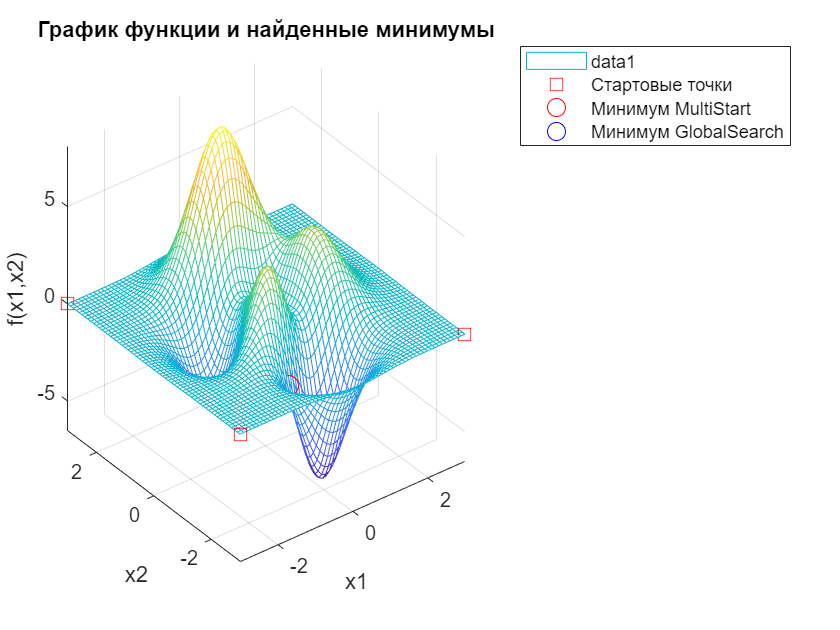


% Построение графика целевой функции
[x1, x2] = meshgrid(-3:0.1:3, -3:0.1:3);
Z = arrayfun(@(x1,x2) myfun1([x1, x2]), x1, x2);  % значения функции на сетке

figure; 
mesh(x1, x2, Z);
hold on;

% стартовые точки красными квадратиками
startValues = arrayfun(@(idx) myfun1(startPoints(idx, :)), 1:nStartPoints);  % Вычисляем значения функции для стартовых точек
plot3(startPoints(:, 1), startPoints(:, 2), startValues, 'rs', 'MarkerSize', 8, 'DisplayName', 'Стартовые точки');

% минимумы на графике
plot3(xm_ms(1), xm_ms(2), fm_ms, 'ro', 'MarkerSize', 10, 'DisplayName', 'Минимум MultiStart');
plot3(xm_gs(1), xm_gs(2), fm_gs, 'bo', 'MarkerSize', 10, 'DisplayName', 'Минимум GlobalSearch');

% границы осей для лучшего представления
xlim([-3 3]);
ylim([-3 3]);
zlim([min(Z(:)) max(Z(:))]);

% Настройка графика
xlabel('x1');
ylabel('x2');
zlabel('f(x1,x2)');
title('График функции и найденные минимумы');
legend('show');
grid on;        
hold off;